# Wrapping up everything

## Collect data from simulation

Initially we have a non-linear model for aircraft flight simulation, from which we can generate some data for random states and random actions. Let's consider states and actions around the x_trim point to generate this data.

clc
clear

% Load models
mdls = lon_LTI_models;
addpath('nl_dynamics')

% Select model (linear and nonlinear)
mdl = mdls.uw; % Select linear model
Ac = mdl.sys.A

Ac =    -0.2743   -0.2178    0.8885   -9.6736
   -2.2507   -9.7801   12.4573    1.6062
   -0.5341   -7.4919  -18.9315         0
         0         0    1.0000         0


Bc = mdl.sys.B(:,1)

Bc =          0
         0
 -102.6120
         0


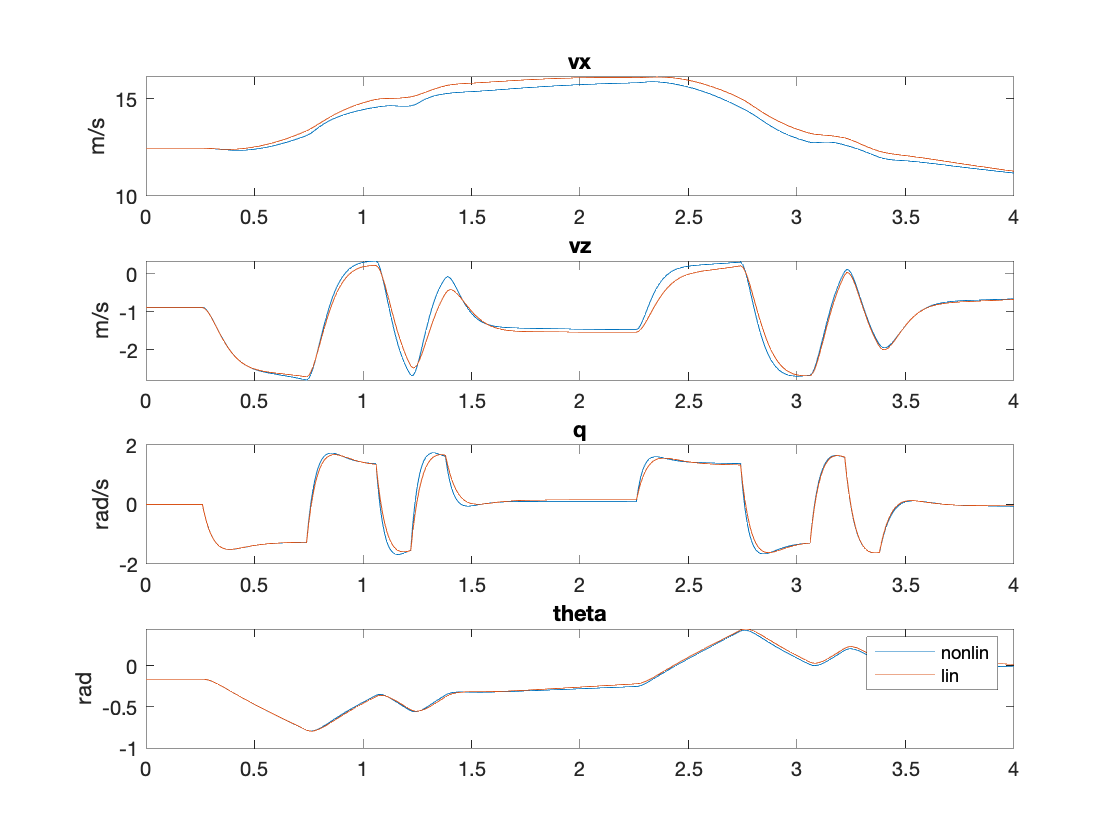

x_trim = mdl.x_trim; nx = length(x_trim);
u_trim = mdl.u_trim(1); nu = length(u_trim);

dyn_func = @dyn_func_uw; % Select (same) nonlinear model

% Create sim for model
dt = 0.01; % Simulation discretization
sim = SimulatorClass(dyn_func, mdl, dt);

% Simulate
t0    = 0;
t_end = 4;
T = (t0:dt:t_end);       % Time vector (s)

% Possible identification inputs
ident_dt = 0.16; % dt in 3*dt, 2*dt, 1*dt, 1*dt
ident2211 = kron([1 1 -1 -1 1 -1], [ones(1, ident_dt/dt)]);
ident3211 = kron([1 1 1 -1 -1 1 -1], [ones(1, ident_dt/dt)]);
identSig = ident3211;

% Create input trajectory containing identification sequence
% U = zeros(2,length(T));
U = repmat(u_trim, 1, length(T));
idxStart = find(T>0.25, 1); U(1, idxStart:idxStart-1+length(identSig)) = deg2rad(20) * identSig; % Insert ident command starting at 0.25s
idxStart = find(T>2.25, 1); U(1, idxStart:idxStart-1+length(identSig)) = deg2rad(20) * -identSig;

% Simulate both nonlinear and linear model in parallel (same initial state and control trajectory)
sim.simulate(t0, t_end, mdl.x_trim, U);
sim.plotStateTrajectrory();


% Assign variables to comply with existing framework
df_u = U(:,1:end-1)';

df_s = sim.state_traj(:,1:end-1)';
df_ns = sim.state_traj(:,2:end)';

df_lin_s = sim.lin_state_traj(:,1:end-1)';
df_lin_ns = sim.lin_state_traj(:,2:end)';

%obtain linearized approximation of next states (Using A(x-x_trim)+B(u-u_trim))
%df_lin_ns = df_s(:,1:4) + dt * (Ac(:,:)*(df_s(:,1:4)-repmat(x_trim',nSteps,1))'+Bc(:,:)*(df_u(:,1)-repmat(u_trim(1)',nSteps,1))')';


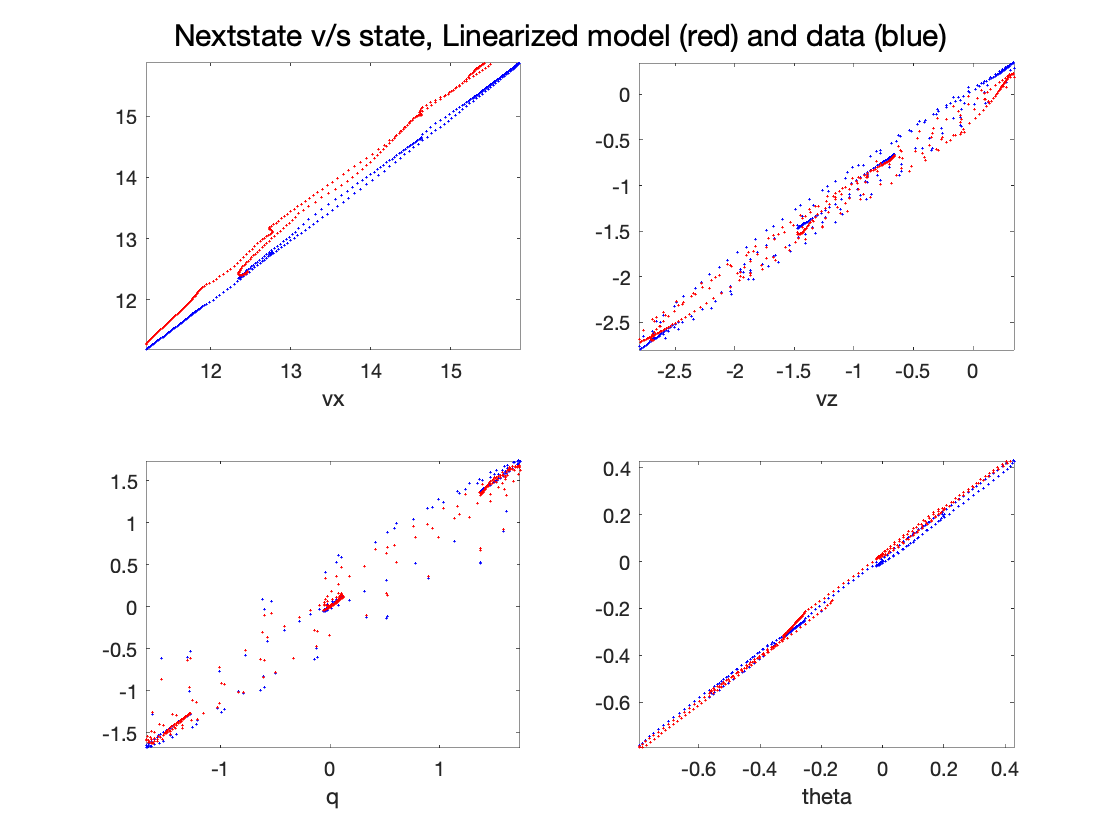

figure
sgtitle("Nextstate v/s state, Linearized model (red) and data (blue)")
for var = 1:4
    subplot(2,2,var)
    plot(df_s(:,var),df_ns(:,var), 'bp', 'MarkerSize', 1) %state against next state
    hold on
    plot(df_s(:,var),df_lin_ns(:,var), 'rp', 'MarkerSize', 1)
    xlim([min(df_s(:,var)),max(df_s(:,var))]);
    ylim([min(df_ns(:,var)),max(df_ns(:,var))]);
    xlabel(mdl.sys.StateName{var});
end

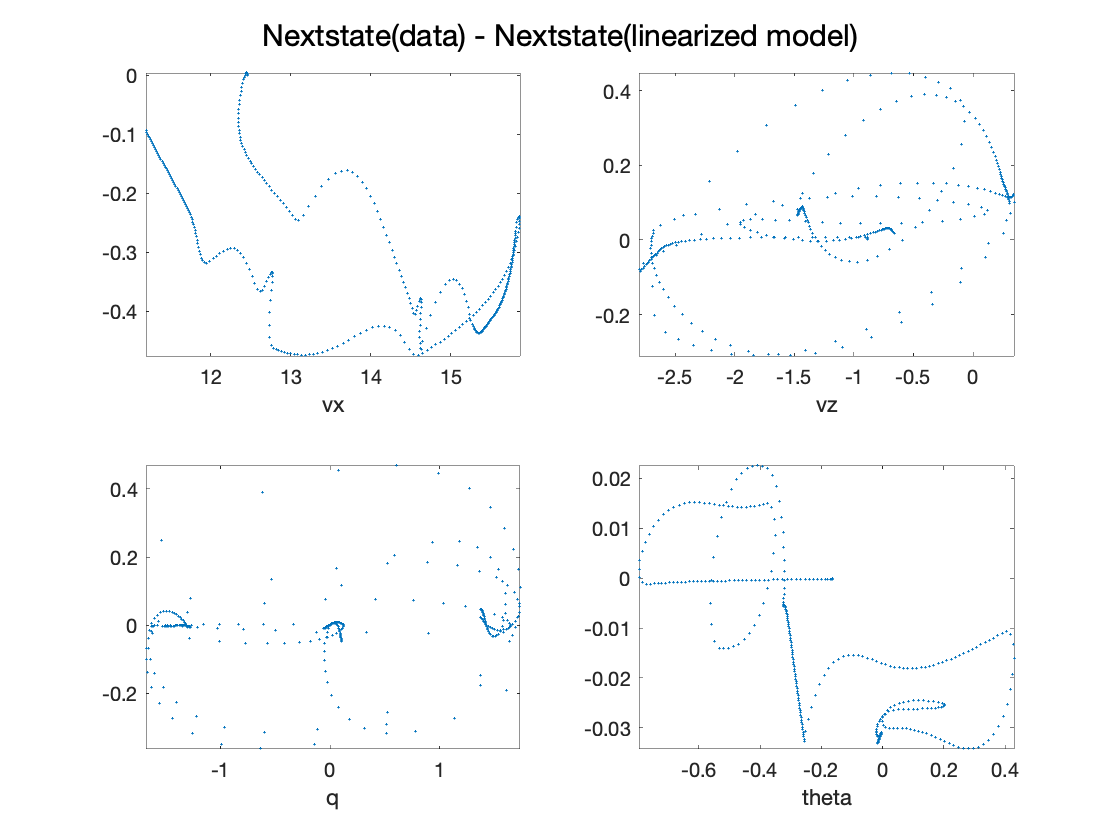

figure
sgtitle("Nextstate(data) - Nextstate(linearized model)")
for var = 1:4
    subplot(2,2,var)
    plot(df_s(:,var),df_ns(:,var)-df_lin_ns(:,var), 'p', 'MarkerSize', 1)
    xlim([min(df_s(:,var)),max(df_s(:,var))]);
    ylim([min(df_ns(:,var)-df_lin_ns(:,var)),max(df_ns(:,var)-df_lin_ns(:,var))]);
    xlabel(mdl.sys.StateName{var});
end

## Set Membership Estimation for dimensional derivatives

I have used the model for xdot=A(x-x_trim)+B*(u-u_trim) as xdot=A*x + B*u plus noise to set the initial guess (remember that the result from m.s. identification is Ax+Bu). This initial guess can be changed with Waibel's XFLR. I have expanded the membership estimation so all values in the A and B matrices can be considered uncertain if its index is in the J set, so adapt to another models can be made easily. This J set to indicate indexes where is uncertainty, has to be though as the A and B matrices were merged into one matrix and then flatten, it follows the numeration used by Tilman previously in h_theta but generalizes for different elements in A and B with uncertainty.

% Initial guess for dynamics: XFLR model
init_model = mdls.xflr_uw;
Ac0 = init_model.sys.A;
Bc0 = init_model.sys.B(:,1);

JA = logical([ 
    1 1 1 0; 
    1 1 1 0; 
    1 1 1 0; 
    0 0 0 0]);
JB = logical([ 
    1; 
    1; 
    1; 
    0]);
J = [JA JB];
idxJ = find(J);   

% Discretize initial model
A0 = eye(nx) + dt * Ac0;
B0 = dt * Bc0;
AB0 = [A0 B0]

AB0 =     0.9990    0.0019    0.0032   -0.0978   -0.0039
   -0.0187    0.9071    0.1109    0.0067   -0.0597
   -0.0024   -0.0724    0.9135         0   -0.7344
         0         0    0.0100    1.0000         0



% this is to indicate to membership function which parameters has uncertainty
np = sum(J(:));
ABi = zeros([size(AB0) np]);
for iP = 1:np
    ABi_ = zeros(size(AB0));
    ABi_(idxJ(iP)) = -dt;  % #jo: I ADDED A MINUS HERE
    ABi(:,:,iP) = ABi_;
end, clear ABi_

% Bounds on delta parameters
H_theta(1:2:2*np, 1:np) = eye(np);
H_theta(2:2:2*np, 1:np) = -eye(np);
h_theta = repmat(10.0 * ones(np,1), 2, 1);

% define initial parameter set
Omega{1} = Polyhedron(H_theta, h_theta);

% Define additive polytopic uncertainty description
w_max = 0.01; 
Hw(1:2:2*nx, 1:nx) = eye(nx);
Hw(2:2:2*nx, 1:nx) = -eye(nx);
hw = w_max * ones(2*nx, 1);
W = Polyhedron(Hw, hw); 
%W = B0 * Polyhedron(Hw, hw); % #jo: I ADDED B* HERE

% instantiate set membership estimator
sm = SetMembership(Omega{1}, W, ABi, AB0);

#### Get Set Membership estimation

nSteps = 100; % for n is toooooooo slow
% the data collection can be done online with this code,
% here is done with the collected samples.
%  I didn't dig too much into the sm function, so maybe the update 
% can be done in one step. This loop is kinda slow...
nData = size(df_s, 1);
%dataIdx = randperm(nData);          % Random selection from dataset
dataIdx = 1:floor(nData/nSteps):nData; dataIdx = dataIdx(1:nSteps);  % Equally distributed selection over time (= downsampling)

dTheta_hat = []; % estimated values

% Use nSteps first random samples for set membership identification
for iStep = 1:nSteps
    id = dataIdx(iStep);
    x = df_lin_s(id,:)';
    u = df_u(id,1)';
    xp = df_lin_ns(id,:)';
    [Omega{iStep+1}, setD{iStep}] = sm.update(xp, x, u);    % update set membership
    dTheta_hat = [dTheta_hat; sm.theta_hat'];  % estimate parameter (center of the estimated set)
end

% this plots the updates for each parameter from the initial guess.
% and updates parameters, to avoid two for loops
%update parameters
dTheta_hat_end = dTheta_hat(end,:)';
AB_vec = vec(AB0);
AB_vec(idxJ) = AB_vec(idxJ) + dTheta_hat_end;
AB_ms = reshape(AB_vec, size(AB0));
A_ms = AB_ms(:,1:nx); B_ms = AB_ms(:,nx+1:nx+nu);
AB_ms = [A_ms B_ms]

AB_ms =     0.9990    0.0019    0.0032   -0.0978   -0.0039
   -0.0187    0.9071    0.1109    0.0067   -0.0597
   -0.0024   -0.0724    0.9135         0   -0.7344
         0         0    0.0100    1.0000         0



A_true = eye(nx) + dt * Ac;
B_true = dt * Bc;
AB_true = [A_true B_true]

AB_true =     0.9973   -0.0022    0.0089   -0.0967         0
   -0.0225    0.9022    0.1246    0.0161         0
   -0.0053   -0.0749    0.8107         0   -1.0261
         0         0    0.0100    1.0000         0


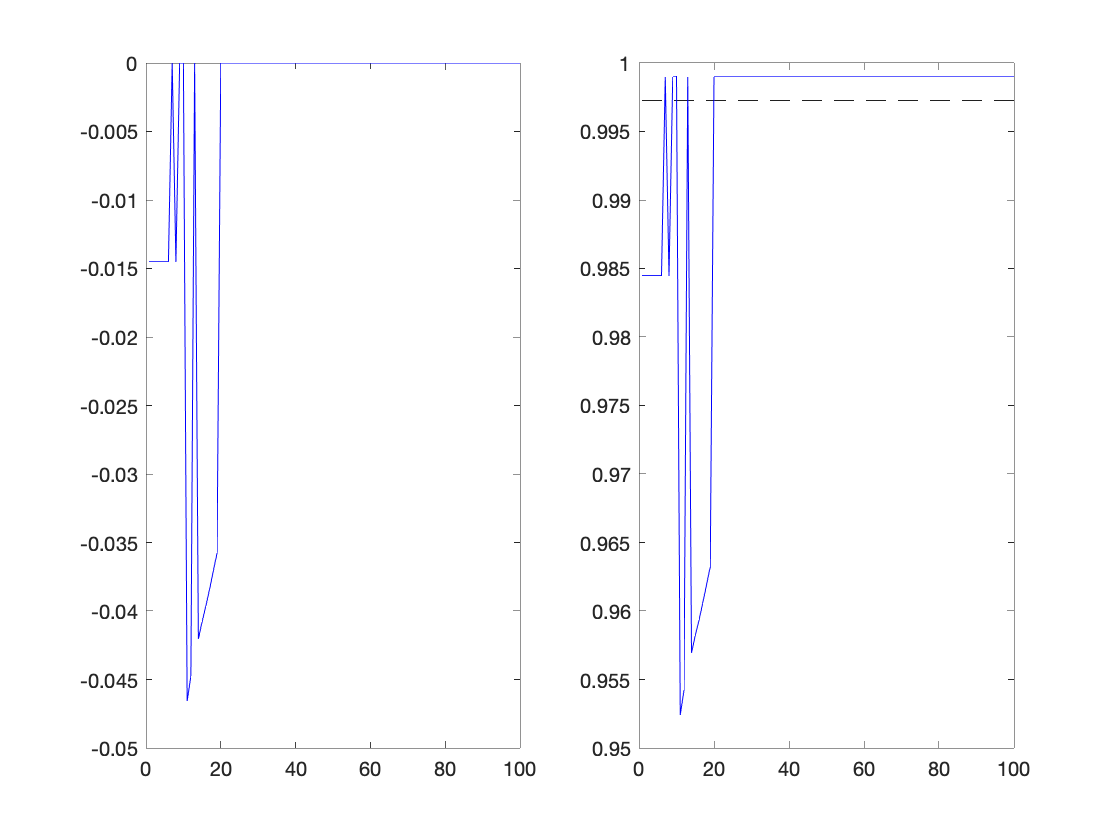

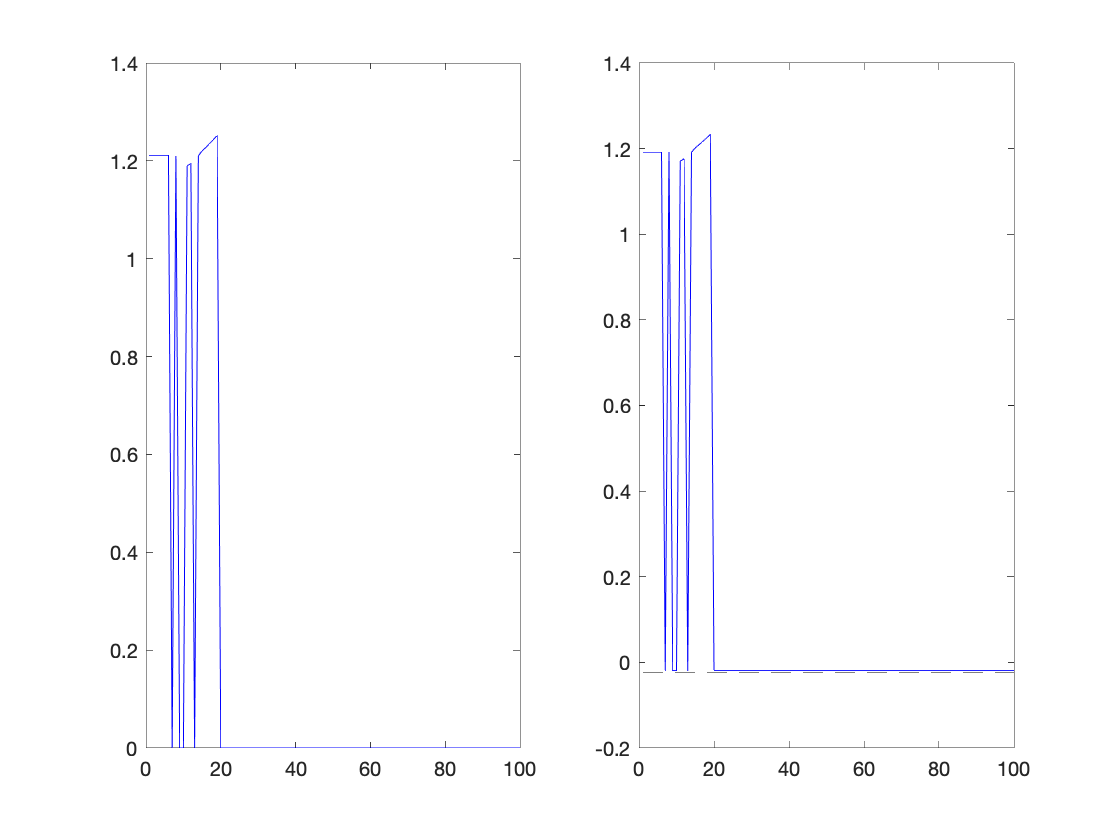

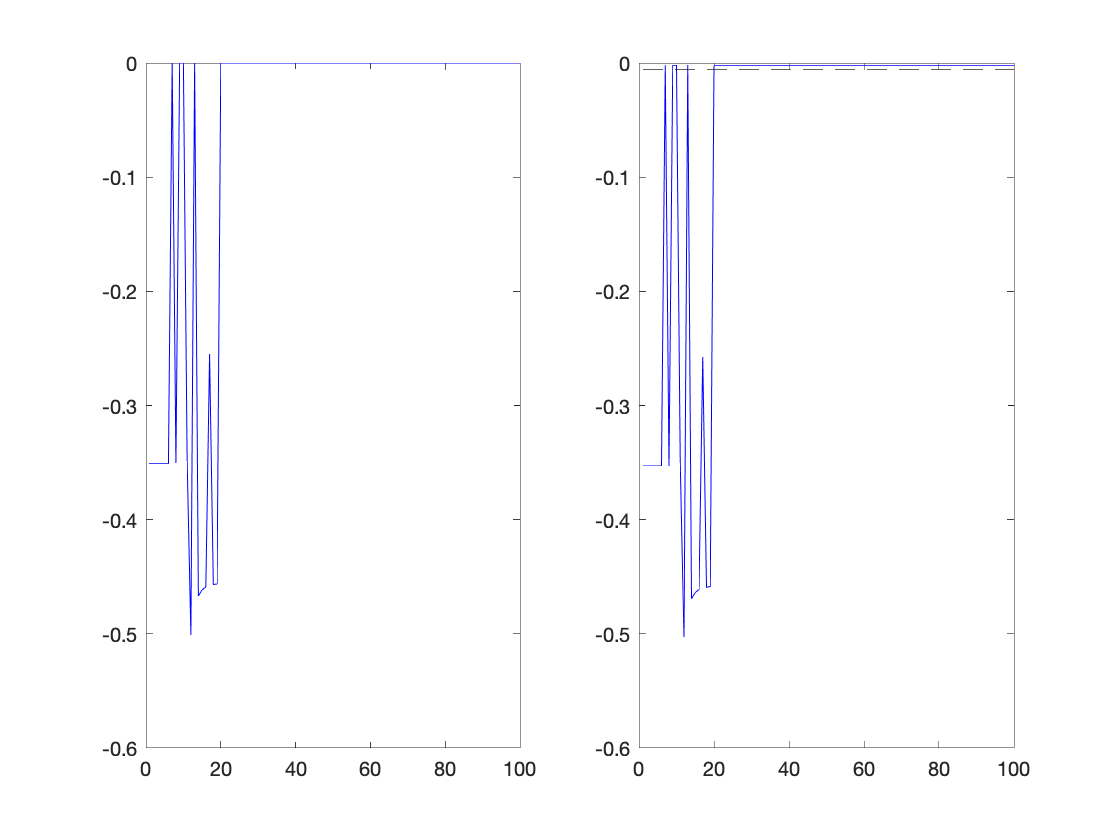

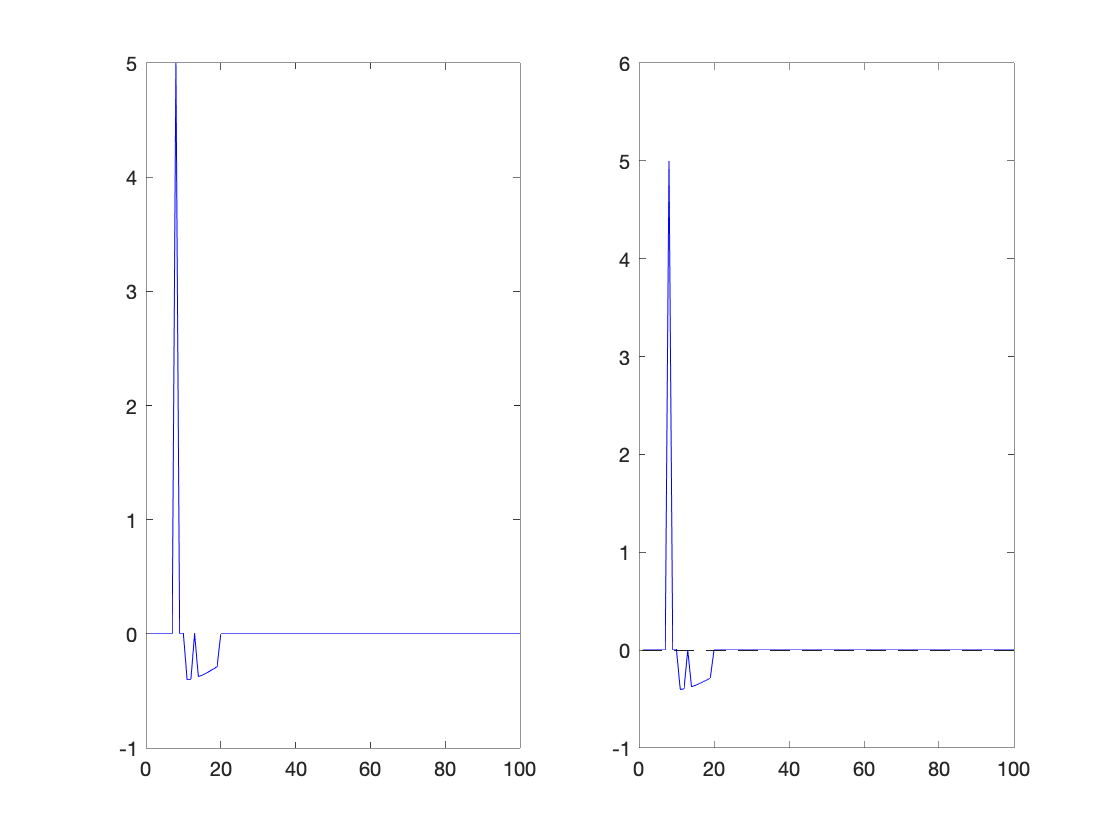

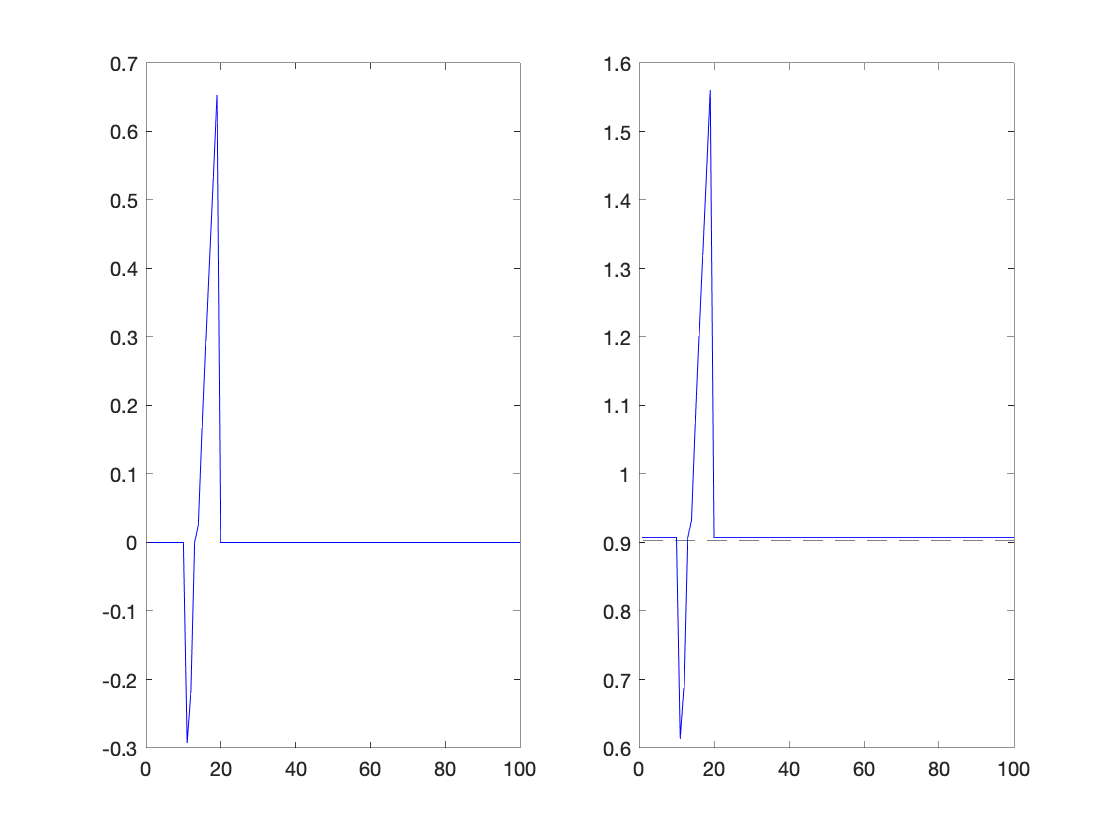

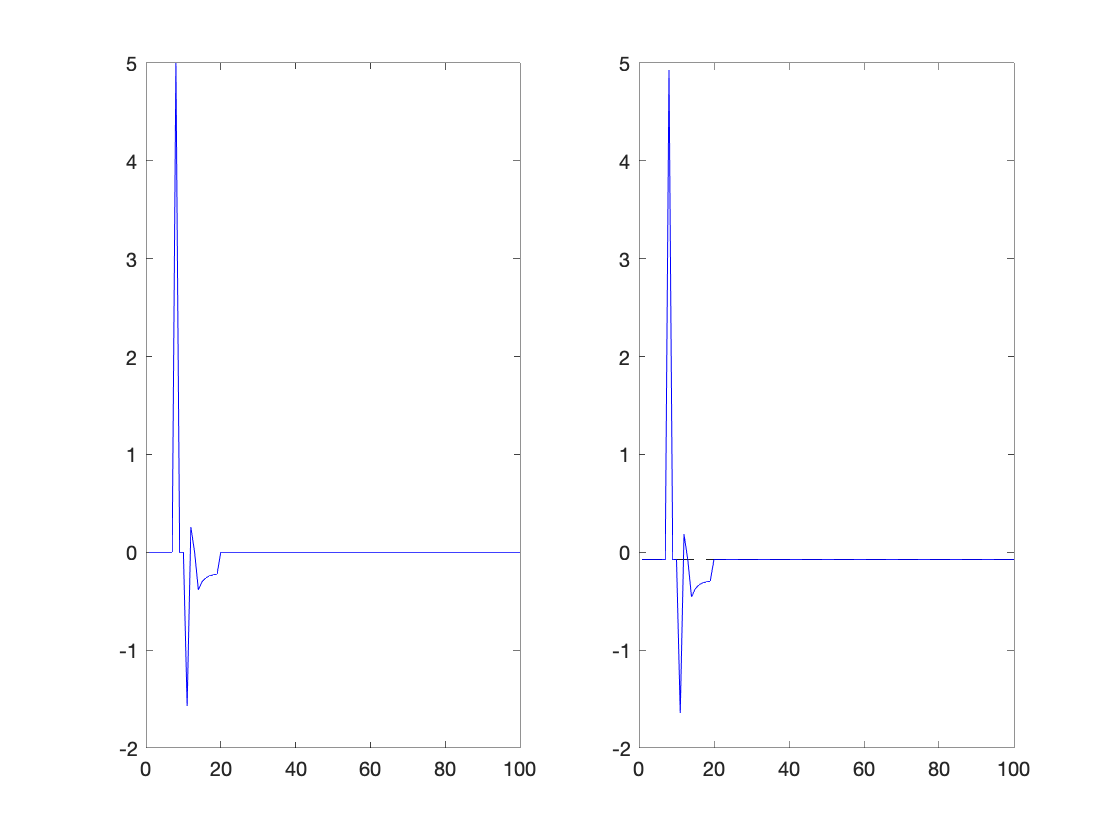

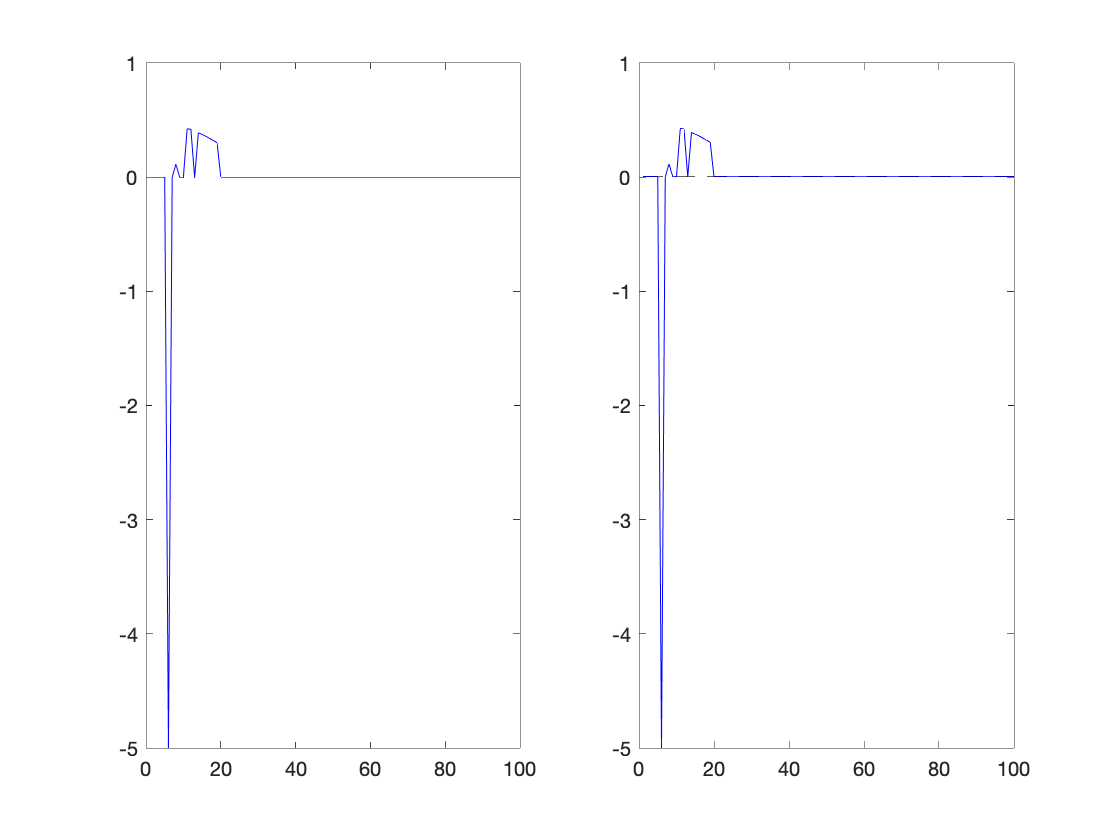

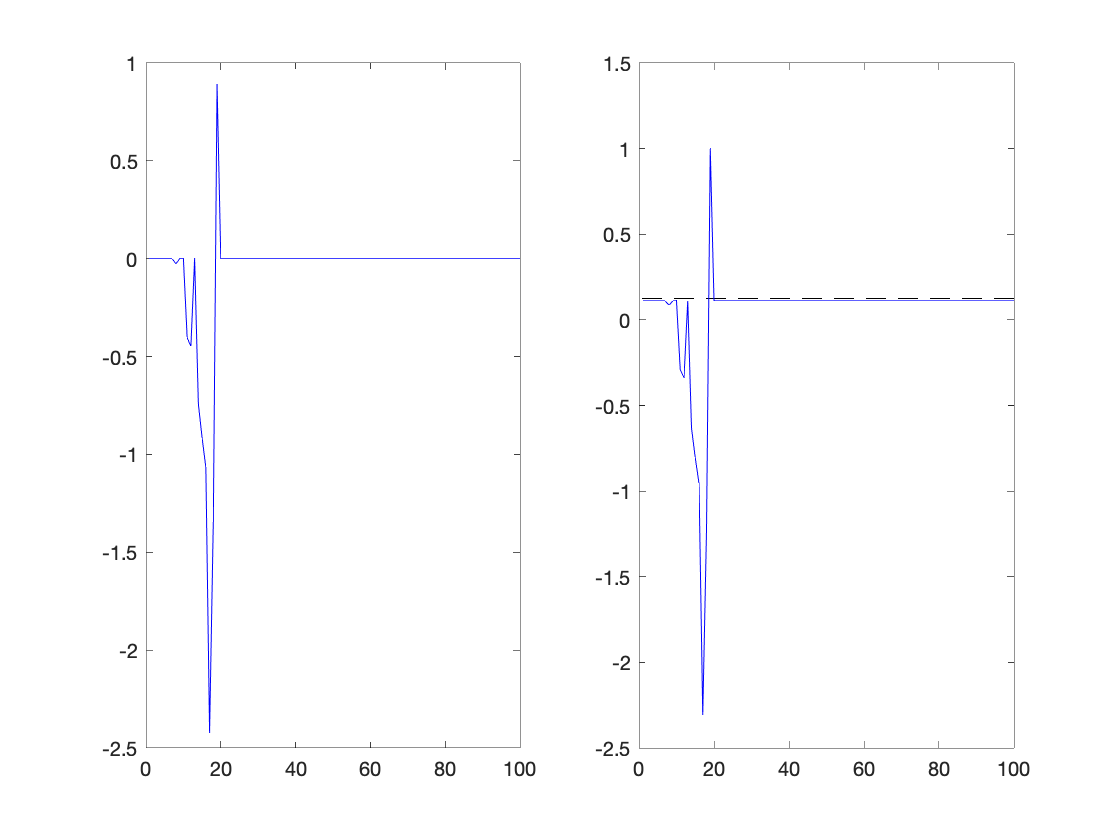

for iP = 1:np
   figure
   subplot(1,2,1) % Delta parameter estimation
   plot(1:nSteps, dTheta_hat(:,iP), 'b');
   
   subplot(1,2,2) % Parameter estimation 
   % True value (linearized dynamics) dashed line
   plot(1:nSteps, repmat(AB_true(idxJ(iP)), nSteps), 'k--'); hold on
   % Estimation history
   plot(1:nSteps, AB0(idxJ(iP))+dTheta_hat(:,iP), 'b');
end


disp('Indices changed in A and B')

Indices changed in A and B


A_ms ~= A0

ans = 4×4 logical array
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


B_ms ~= B0

ans = 4×1 logical array
   0
   0
   0
   0



return

These membership estimations should'nt converge, as the initial guess is the horizontal line, its a different plot that the one used before.


figure
sgtitle("Nextstate v/s state, Linearized model (red), data (blue), M.S model (green)")
states=["Va","alpha","q","gamma"];
for var = 1:4
    subplot(2,2,var)
    plot(df_s(:,var),df_ns(:,var), 'bp', 'MarkerSize', 0.5) %state against next state
    hold on
    plot(df_s(:,var),df_lin_ns(:,var), 'rp', 'MarkerSize', 0.5)
    hold on
    plot(df_s(:,var),df_ms_ns(:,var), 'gp', 'MarkerSize', 1)
    xlim([min(df_s(:,var)),max(df_s(:,var))]);
    ylim([min(df_ns(:,var)),max(df_ns(:,var))]);
    xlabel(states(var));
end

figure
sgtitle(["Nextstate(data) - Nextstate(linearized model) [blue]"; ...
    "and Nextstate(data) - Nextstate(membership model) [green]"])
for var = 1:4
    subplot(2,2,var)
    plot(df_s(:,var),df_ns(:,var)-df_lin_ns(:,var), 'bp', 'MarkerSize', 1)
    hold on;
    plot(df_s(:,var),df_ns(:,var)-df_ms_ns(:,var), 'gp', 'MarkerSize', 1)
    xlim([min(df_s(:,var)),max(df_s(:,var))]);
    xlabel(states(var));
end

## Maneuver with linearized model and membership model the non linear simulator

In constrast with the membership model, the linearized model can not be obtained without aircraft parameter knowledgement. There are two nominal MPC functions implemented, as the linearized model works with xdot=A(x-xtrim).... and the membership with xdot=Ax+Bu...

% Define maneuver (this maneuver is a stepwise trajectory tracking maneuver
% looking to align alpha and gamma):
alpha_ref=[repmat(deg2rad(-4),1,200) repmat(deg2rad(0),1,500)];
gamma_ref=alpha_ref;

%with linearized model
x_ini=x_trim';
x0=x_ini';
X_lin=x0;
for t = 1:400
    [U,X,u]=MPC_nom_lin(x0,dt,alpha_ref(:,t:end),gamma_ref(:,t:end),20);
    x0=x0+dyn_func_gam(x0, u)*dt;
    X_lin=cat(2,X_lin,x0);
    if isnan(u)
        break
    end
end

%with membership model
x_ini=x_trim';
x0=x_ini';
X_ms=x0;
for t = 1:400
    [U,X,u]=MPC_nom(A_ms,B_ms,x0,dt,alpha_ref(:,t:end),gamma_ref(:,t:end),20);
    x0=x0+dyn_func_gam(x0, u)*dt;
    X_ms=cat(2,X_ms,x0);
    if isnan(u)
        break
    end
end

figure
subplot(3,1,1)
plot(X_lin(2,:),"r")
hold on
plot(X_ms(2,:),"g")
hold on
plot(alpha_ref,"k")
legend(["linearized","M.S","ref."])
ylabel("alpha")
subplot(3,1,2)
plot(X_lin(4,:),"r")
hold on
plot(X_ms(4,:),"g")
hold on
plot(gamma_ref,"k")
legend(["linearized","M.S","ref."])
ylabel("gamma")

figure
sgtitle("Objective function evaluation")
plot((X_lin(2,:)-alpha_ref(1,1:size(X_lin,2))).^2+(X_lin(4,:)-gamma_ref(1,1:size(X_lin,2))).^2,"r")
hold on
plot((X_ms(2,:)-alpha_ref(1,1:size(X_ms,2))).^2+(X_ms(4,:)-gamma_ref(1,1:size(X_ms,2))).^2,"g")
legend(["linearized","M.S"])

figure
sgtitle("Cumulative objective function evaluation")
plot(cumsum((X_lin(2,:)-alpha_ref(1,1:size(X_lin,2))).^2+(X_lin(4,:)-gamma_ref(1,1:size(X_lin,2))).^2),"r")
hold on
plot(cumsum((X_ms(2,:)-alpha_ref(1,1:size(X_ms,2))).^2+(X_ms(4,:)-gamma_ref(1,1:size(X_ms,2))).^2),"g")
legend(["linearized","M.S"])
